# Analyze the trichromatic matches to white reported in Maxwell 1860

Maxwell's original data were matches of three spectral lights to a white.  The values of these matches are reported in Table IV of his 1860 paper.  

To calculate the color matching functions, Maxwell carefully selected the wavelengths in his matches.  He used a cleverl configuration that enabled him to calculate the CMFs from simple algebraic methods. The derived CMFs are presented in Table VI and Table IX in the original 1860 paper, and we rely on those for the main paper.

We realized that it would have been possible, using modern methods, to calculate Maxwell's color-matching functions directly from the matches to white in Table IV.  He didn't quite collect enough data.  But we show how he might have done it, and we then use our knowledge of null spaces and such to show that it even works well with the published data, if we ask for a little smoothness in the solution.

This analysis is carried out for just one of the subjects because Maxwell only provides the data in this format for one of his subjects. 

This approach fits the CIE standards well, too. It isn't necessary to use the method, but we did it just to see if we could.  And who knows.  Some day ...

## **Initialize ISET**

ieInit;

## Judd wavelength correspondences

We will adjust these by 10 nm later.

juddWave = [
    20 663.2
    24 630.2
    28 606.4
    32 583.1
    36 562.5
    40 544.9
    44 528.1
    48 508.6
    52 499.7
    56 486.4
    60 475.1
    64 465.9
    68 456.9
    72 449.4
    76 441.2
    80 434.2];

## Table IV Observer K the mean of four sets of observations

All of these spectral vectors (columns) match the standard white. The values are the average of four matches by OBS K.  Each row represents a wavelength of the primaries used for the match.  The columns 

The original data from the paper are here.  Note that the wavelength index 46 is only used as a primary light once (appears once in the row for 46). Could that match actually be a 48 or a 44?  If it is 44 that would be the three primaries match to white, and it would make more sense of the data.

%{
table4Matches = [
    20     44.3  0     0     0     0     0     0     0     0     0     0     0     0     0     
    24     0     0     0   6.4     15.3  19.8  21.2  22    21.7  20.5  19.7  18.0  17.5  18.3  
    28     0     16.1  0     0     0     0     0     0     0     0     0     0     0     0     
    32     0     0     22.0  0     0     0     0     0     0     0     0     0     0     0     
    36     0     0     0     25.2  0     0     0     0     0     0     0     0     0     0     
    40     0     0     0     0     26.0  0     0     0     0     0     0     0     0     0     
    44     31    25.6  12.1  0     0     0     0     0     10.4  23.7  30.3  31.2  30.7  33.2     
    46     0     0     0     0     0     35.0  0     0     0     0     0     0     0     0     
    48     0     0     0     0     0     0     41.4  0     0     0     0     0     0     0     
    52     0     0     0     0     0     0     0     62    0     0     0     0     0     0     
    56     0     0     0     0     0     0     0     0     61.7  0     0     0     0     0     
    60     0     0     0     0     0     0     0     0     0     40.5  0     0     0     0     
    64     0     0     0     0     0     0     0     0     0     0     33.7  0     0     0     
    68     27.7  30.6  30.6  31.3  30.7  30.2  27.0  13    0     0     0     0     0     0     
    72     0     0     0     0     0     0     0     0     0     0     0     32.3  0     0     
    76     0     0     0     0     0     0     0     0     0     0     0     0     44    0     
    80     0     0     0     0     0     0     0     0     0     0     0     0     0     63.7    
];
%}


Here, I adjusted the table, setting the 46 value to 44.  That way, we  include the primaries match to the white. 

table4Matches = [
    20     44.3  0     0     0     0     0     0     0     0     0     0     0     0     0     
    24     0     0     0   6.4     15.3  19.8  21.2  22    21.7  20.5  19.7  18.0  17.5  18.3  
    28     0     16.1  0     0     0     0     0     0     0     0     0     0     0     0     
    32     0     0     22.0  0     0     0     0     0     0     0     0     0     0     0     
    36     0     0     0     25.2  0     0     0     0     0     0     0     0     0     0     
    40     0     0     0     0     26.0  0     0     0     0     0     0     0     0     0     
    44     31    25.6  12.1  0     0     35.0  0     0     10.4  23.7  30.3  31.2  30.7  33.2     
    48     0     0     0     0     0     0     41.4  0     0     0     0     0     0     0     
    52     0     0     0     0     0     0     0     62    0     0     0     0     0     0     
    56     0     0     0     0     0     0     0     0     61.7  0     0     0     0     0     
    60     0     0     0     0     0     0     0     0     0     40.5  0     0     0     0     
    64     0     0     0     0     0     0     0     0     0     0     33.7  0     0     0     
    68     27.7  30.6  30.6  31.3  30.7  30.2  27.0  13    0     0     0     0     0     0     
    72     0     0     0     0     0     0     0     0     0     0     0     32.3  0     0     
    76     0     0     0     0     0     0     0     0     0     0     0     0     44    0     
    80     0     0     0     0     0     0     0     0     0     0     0     0     0     63.7    
];

## Adjustment of the wavelength by 10 nm 

Judd provides a very good estimate of the true wavelengths in his  paper on Maxwell.  But I (BW) think it may be off by about 10nm based on the quality of the fits.  That is justified in s_maxwellCMF2CIEshift.m Here, we adjust the Judd wavelengths by a small amount before we do the fits.

juddAdjust = 10;  % Adjustment in nm
table4Matches(:,1) = juddWave(:,2)-juddAdjust;   % Set to wavelength
table4Matches = flipud(table4Matches);

% Wave is now the adjusted wavelengths
wave    = table4Matches(:,1);
matches = table4Matches(:,2:end);

## Find the best fit to all ones

The Maxwell data are all matches to a common, white light. To derive the color matching functions, we need to find three independent vectors, CMF_i, that produce a constant value 

The column vector on the LHS is constant because the subject always matched the same light. The matrix 'matches' has wavelength (16) in the columns, and the number of matches (14) in the rows.

Because there are 16 wavelengths and only 14 matches, we need an extra constraint. We used a Tikhonov regularizer to calculate a relatively smooth solution.

% Puts 1s in the columns
O = ones(size(matches',1),1);
lambda = logspace(-2,3,6);  % Different size of the regularizer

% The Maxwell CMF solution, constrained by different levels of
% smoothness (lambda)
y = zeros(numel(wave),numel(lambda));
for ii = 1:numel(lambda)
    y(:,ii) = ieTikhonov(matches',O,'smoothness',lambda(ii));
end

## How good are the smooth'd fits?

Columns increasing in smoothness parameter, lambda.  All solutions should be 1.  The first three are pretty good.

tmp = matches'*y

tmp =     1.0000    1.0000    1.0000    0.9996    0.9981    0.9977
    1.0000    1.0000    0.9996    0.9969    0.9896    0.9821
    1.0000    1.0000    1.0000    0.9999    0.9946    0.9600
    1.0000    1.0000    1.0000    1.0001    0.9952    0.9502
    1.0000    1.0000    0.9999    0.9990    0.9970    0.9816
    1.0000    1.0001    1.0005    1.0046    1.0211    1.0459
    1.0000    1.0000    1.0000    1.0003    1.0031    1.0211
    1.0000    1.0000    1.0000    0.9997    0.9986    1.0087
    1.0000    1.0000    1.0001    1.0006    1.0034    1.0049
    1.0000    1.0000    0.9999    0.9988    0.9926    0.9880


## Are the smooth solutions within a linear transformation of Stockman?

% Read in the Stockman curves
stockman = ieReadSpectra('stockmanenergy',wave);

% The first few levels of smoothness are all OK. So I illustrate with the first one 
% Use the CMF estimated and see if we can get there from the Stockman data.
n = 1;
maxwell = y(:,n);

We want to transform from the Stockman to this Maxwell vector


$$M=S*T$$


We solve for $T$ and ask how close $S*T$ comes to $M$

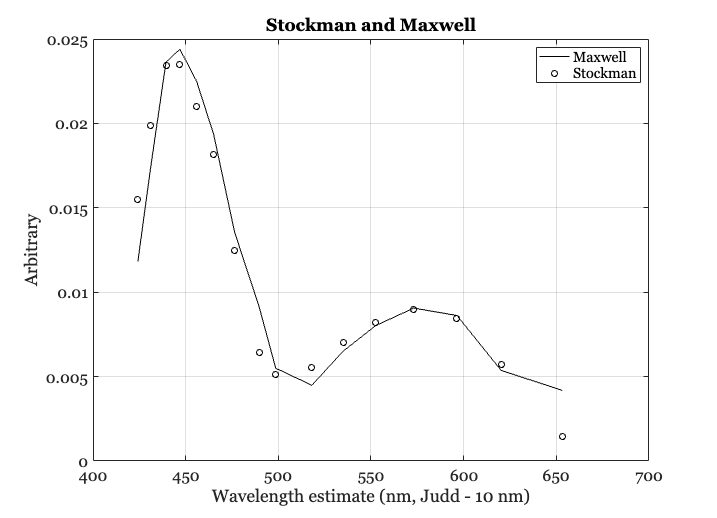

stock2maxwell = stockman \ maxwell;
estMaxwell = stockman*stock2maxwell;

ieNewGraphWin; 
plot(wave,maxwell,'k-',wave,estMaxwell,'ko');
xlabel(sprintf('Wavelength estimate (nm, Judd - %d nm)',juddAdjust));
ylabel('Arbitrary'); title('Stockman and Maxwell');
grid on; legend('Maxwell','Stockman')

## Two other Maxwell CMFs can be found by adding vectors from the null space of matches

This is a new idea.

We set up an equation to solve for vectors in the null space of the 'matches' matrix. We can add null space vectors into the maxwell solution we found.  They will also produce a solution of all 1s. Then we use the smooth maxwell solution plus the two null space vectors as possible fits to the Stockman curves.

% Here is the null space.
A = matches';
N = null(A);

These vectors relatively smooth.  But we could smooth them more if we like.

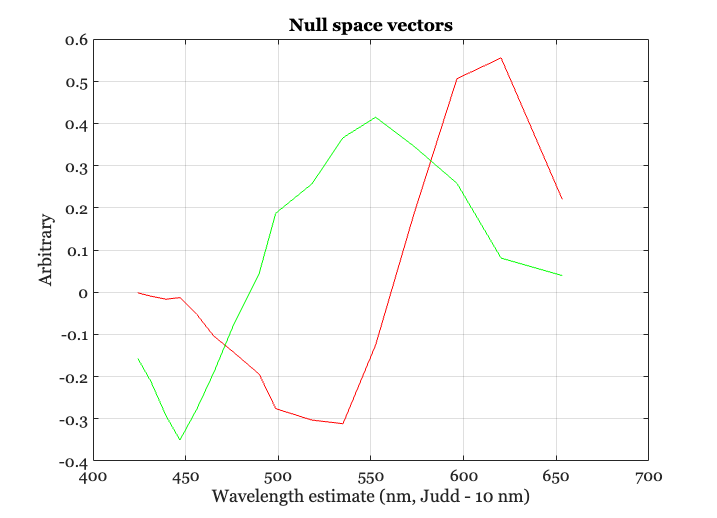

ieNewGraphWin;
plot(wave,N); grid on;
xlabel(sprintf('Wavelength estimate (nm, Judd - %d nm)',juddAdjust));
ylabel('Arbitrary');
title('Null space vectors');

## Fit Stockman to the three curves

Create the full Maxwell CMFs as the smooth solution and the two null space vectors. Find the linear transform from the full Maxwell CMFs to the Stockman curves

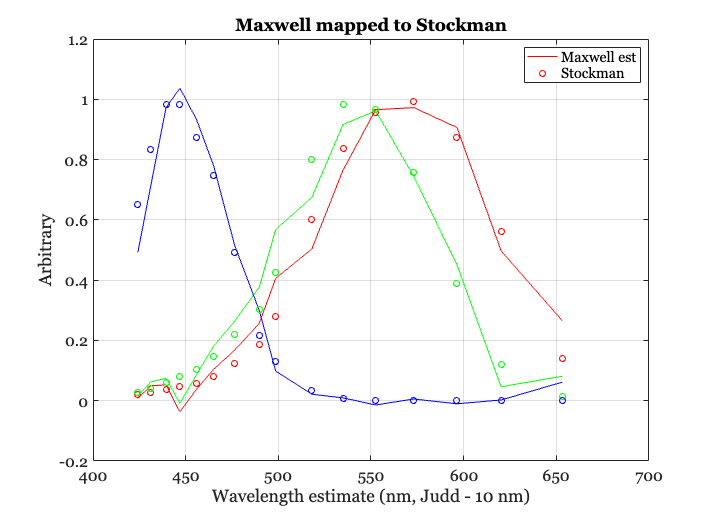


Maxwell = [ieScale(maxwell(:),1), ieScale(N(:,1),1), ieScale(N(:,2),1)];
lTransform = Maxwell \ stockman;

% Here is the estimate from Maxwell to Stockman.
estStockman = Maxwell * lTransform;

ieNewGraphWin;
plot(wave,estStockman); grid on; hold on;
plot(wave,stockman(:,1),'ro',wave,stockman(:,2),'go',wave,stockman(:,3),'bo');
xlabel(sprintf('Wavelength estimate (nm, Judd - %d nm)',juddAdjust));
ylabel('Arbitrary');
title('Maxwell mapped to Stockman')
legend('Maxwell est','','','Stockman','','');

## Fit from  Stockman to the Maxwell CMFs

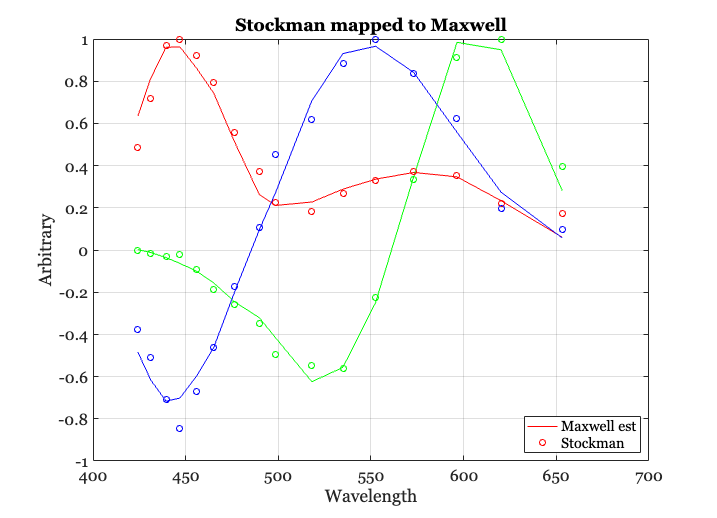

lTransform = stockman \ Maxwell;
estMaxwell = stockman *lTransform;

ieNewGraphWin;
plot(wave,estMaxwell); grid on; hold on;
plot(wave,Maxwell(:,1),'ro',wave,Maxwell(:,2),'go',wave,Maxwell(:,3),'bo');
xlabel('Wavelength'); ylabel('Arbitrary');
title('Stockman mapped to Maxwell')
legend('Maxwell est','','','Stockman','','','Location','southeast');